% MATLAB Live Script to Calculate and Visualize the Camera Placement for a 3D Printer

%% Define Parameters
width = 250;   % Width of the print area including margins (mm)
height = 300;  % Depth of the print area (mm)
fov_horizontal = 75; % Horizontal field of view (degrees)
resolution = [1920, 1080]; % Full HD resolution of the camera (pixels)

% Static camera position
camera_x = 0;      % Camera is centered along the x-axis
camera_y = -150;   % Camera is positioned statically behind the printer
camera_z = 150;    % Camera height statically set

% Define the target point (center of the print bed)
target_x = 0;
target_y = height / 2;
target_z = 0;

% Calculate direction vector from camera to target
direction_vector = [target_x - camera_x, target_y - camera_y, target_z - camera_z];
direction_unit = direction_vector / norm(direction_vector);

% Extend the cone beyond the target to ensure it intersects the z=0 plane
cone_extension_factor = 2; % Extend the cone 2 times the current length
cone_height = norm(direction_vector) * cone_extension_factor;
cone_radius = cone_height * tan(deg2rad(fov_horizontal / 2));

% Generate cone geometry
[x_cone, y_cone, z_cone] = cylinder([0 cone_radius], 50);
z_cone = z_cone * cone_height;

% Rotate and translate the cone to align with the direction vector
R = vrrotvec2mat(vrrotvec([0, 0, 1], direction_unit));
cone_points = [x_cone(:), y_cone(:), z_cone(:)] * R';
cone_points(:, 1) = cone_points(:, 1) + camera_x;
cone_points(:, 2) = cone_points(:, 2) + camera_y;
cone_points(:, 3) = cone_points(:, 3) + camera_z;

x_cone = reshape(cone_points(:, 1), size(x_cone));
y_cone = reshape(cone_points(:, 2), size(y_cone));
z_cone = reshape(cone_points(:, 3), size(z_cone));

%% Print Results
fprintf('Camera Placement Parameters:\n');

Camera Placement Parameters:


fprintf('  Field of View (Horizontal): %.2f°\n', fov_horizontal);

  Field of View (Horizontal): 75.00°


fprintf('  Camera Position: (X=%.2f mm, Y=%.2f mm, Z=%.2f mm)\n', camera_x, camera_y, camera_z);

  Camera Position: (X=0.00 mm, Y=-150.00 mm, Z=150.00 mm)


fprintf('  Target Point: (X=%.2f mm, Y=%.2f mm, Z=%.2f mm)\n', target_x, target_y, target_z);

  Target Point: (X=0.00 mm, Y=150.00 mm, Z=0.00 mm)


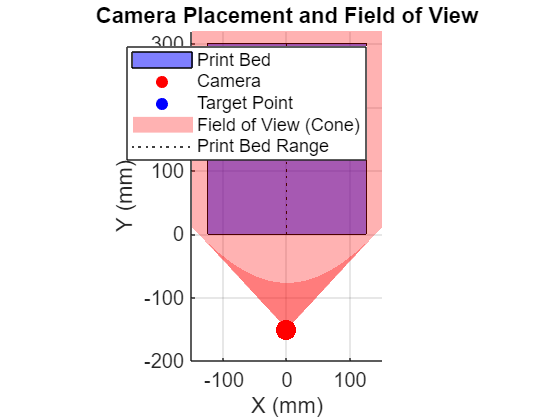


%% Plotting
figure;
hold on; grid on; axis equal;
axis([-150 150 -200 320 0 320]); % Restrict the plot limits

% Define print bed as a blue cuboid
bed_vertices = [
    -width/2, 0, 0;
     width/2, 0, 0;
    -width/2, height, 0;
     width/2, height, 0;
    -width/2, 0, 10;
     width/2, 0, 10;
    -width/2, height, 10;
     width/2, height, 10
];
fill3(bed_vertices([1, 2, 4, 3], 1), bed_vertices([1, 2, 4, 3], 2), bed_vertices([1, 2, 4, 3], 3), 'b', 'FaceAlpha', 0.5);

% Plot camera position as a red point
scatter3(camera_x, camera_y, camera_z, 100, 'r', 'filled');

% Plot target point as a blue point
scatter3(target_x, target_y, target_z, 100, 'b', 'filled');

% Plot the cone
surf(x_cone, y_cone, z_cone, 'FaceAlpha', 0.3, 'EdgeColor', 'none', 'FaceColor', 'r');

% Plot movement range of the print bed as black dotted lines
line([-width/2, width/2], [0, 0], [0, 0], 'Color', 'k', 'LineStyle', ':');
line([0, 0], [0, height], [0, 0], 'Color', 'k', 'LineStyle', ':');

% Labels and visualization
xlabel('X (mm)'); ylabel('Y (mm)'); zlabel('Z (mm)');
title('Camera Placement and Field of View');
legend('Print Bed', 'Camera', 'Target Point', 'Field of View (Cone)', 'Print Bed Range');


function R = vrrotvec2mat(vrrotvec)
    % Helper function to create a rotation matrix from a rotation vector
    s = sin(vrrotvec(4));
    c = cos(vrrotvec(4));
    t = 1 - c;
    x = vrrotvec(1); y = vrrotvec(2); z = vrrotvec(3);
    R = [t*x*x + c,   t*x*y - s*z, t*x*z + s*y;
         t*x*y + s*z, t*y*y + c,   t*y*z - s*x;
         t*x*z - s*y, t*y*z + s*x, t*z*z + c];
end
